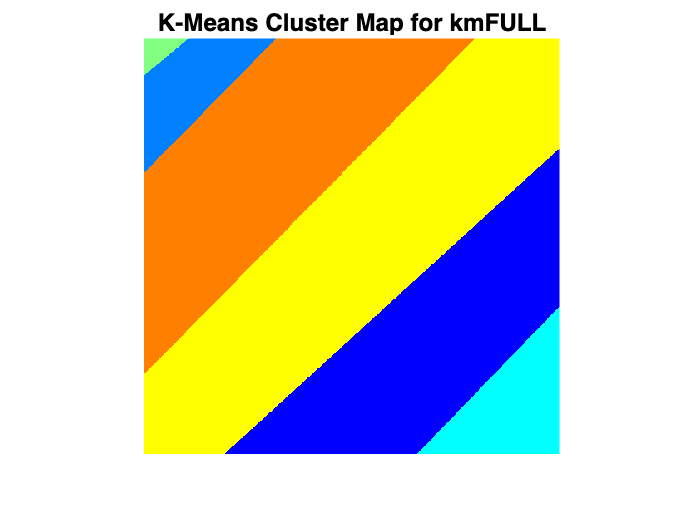

% Example calls to the function for each dataset
plotKMeansClusterMap('KmediodFULLcluster.mat', 'kmFULL');

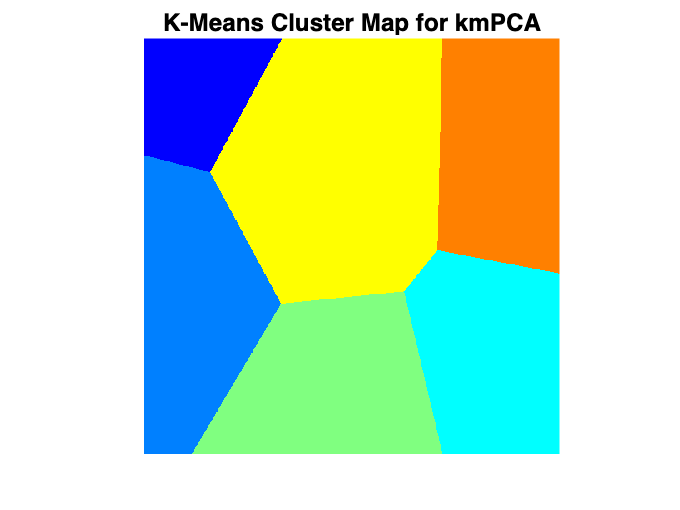

plotKMeansClusterMap('KmediodPCAcluster.mat', 'kmPCA');

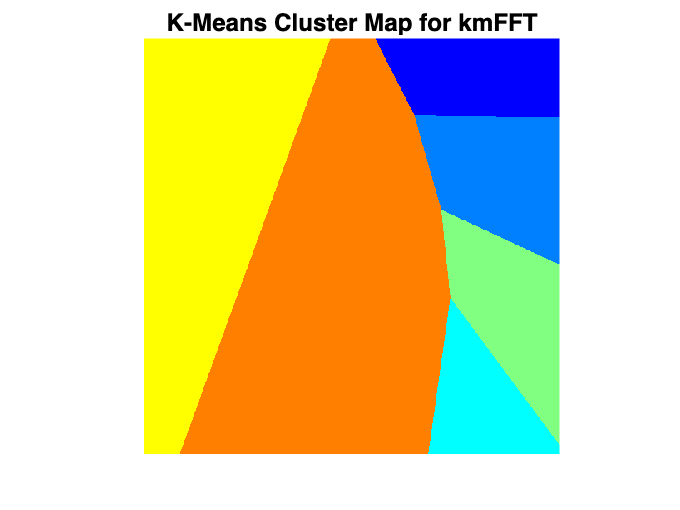

plotKMeansClusterMap('KmediodFFTcluster.mat', 'kmFFT');

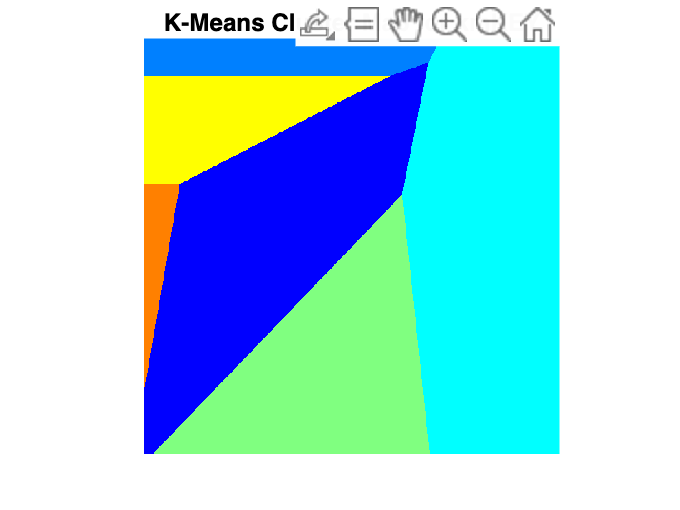

plotKMeansClusterMap('KmediodKEYCluster.mat', 'kmKEY');

function plotKMeansClusterMap(matFile, dataFieldName)
    % Load the dataset
    data = load(matFile);

    % Extract centroids assuming centroids are stored in a 2D format
    centroids = data.(dataFieldName).C; % Check the structure of data file for actual variable names
    if size(centroids, 2) < 2
        error('Centroids must have at least two dimensions.');
    end

    % Define the grid dimensions based on the range of centroids
    xMin = min(centroids(:,1));
    xMax = max(centroids(:,1));
    yMin = min(centroids(:,2));
    yMax = max(centroids(:,2));
    [X, Y] = meshgrid(linspace(xMin, xMax, 500), linspace(yMin, yMax, 500)); % Grid size of 500x500

    % Flatten the grid to make a list of coordinate pairs for distance calculation
    XY = [X(:) Y(:)];

    % Calculate distances from each grid point to each centroid using only the first two columns of centroids
    distances = pdist2(XY, centroids(:, 1:2));

    % Find the closest centroid for each grid point
    [~, labels] = min(distances, [], 2);
    labels = reshape(labels, size(X));

    % Plot the result as an image
    figure;
    imagesc(label2rgb(labels, 'jet', 'w')); % Using imagesc for better control over aspect
    axis image off; % Hide axis for a cleaner look
    title(sprintf('K-Means Cluster Map for %s', dataFieldName));

    % Save the image to a file
    saveas(gcf, [dataFieldName, '_ClusterMap.png']);
end